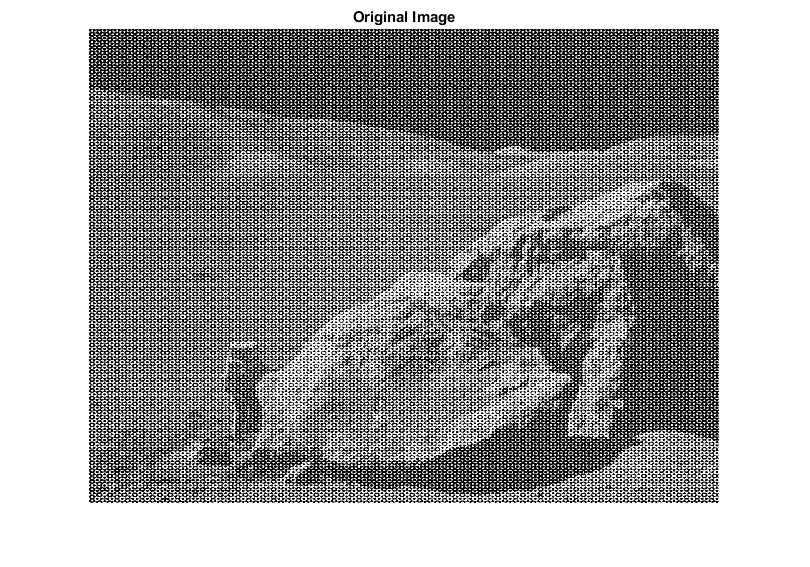

clc
clear all
close all
img_input=imread('E:\Studies\7th Semester\DSP lab\Project\Noisy_img.tif'); %read image
imshow(img_input); title("Original Image")

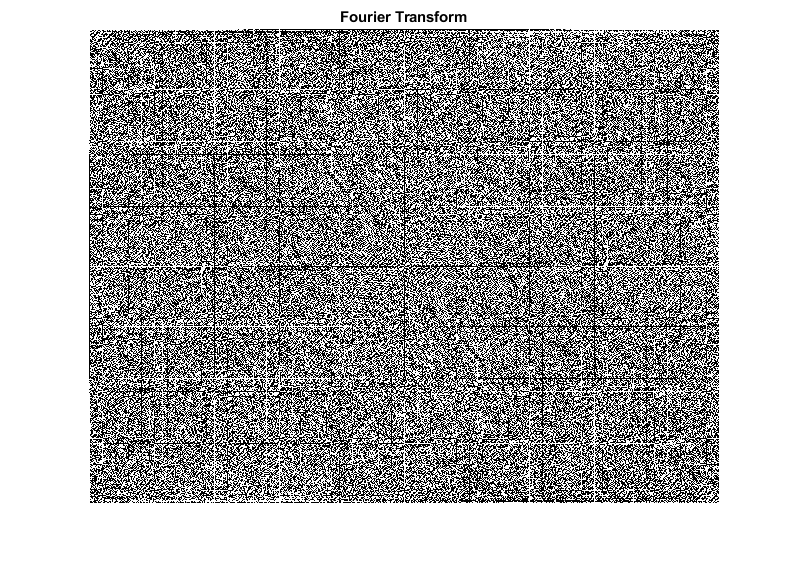

input = im2double(img_input);
%%% Computing the Fourier Transform %%%

[M, N] = size(input); % Calculating Rows and Col
Wm = zeros(M, M);
Wn = zeros(N, N);
for x = 1:M-1
    for y = 1:N-1
    input(x, y) = input(x, y) * (-1)^(x + y);
    end
end
for k = 0:M-1
    for n = 0:M-1
    Wm(k+1, n+1) = exp(-1i * pi * 2 * k * n/ M);
    end
end

for k = 0:N-1
    for n = 0:N-1
    Wn(k+1, n+1) = exp(-1i * pi * 2 * k * n / N);
    end
end

Fft = Wm * input * Wn; %FFT of our image
FFT = (fft2(double(input)));
imshow(real(Fft)); title('Fourier Transform')

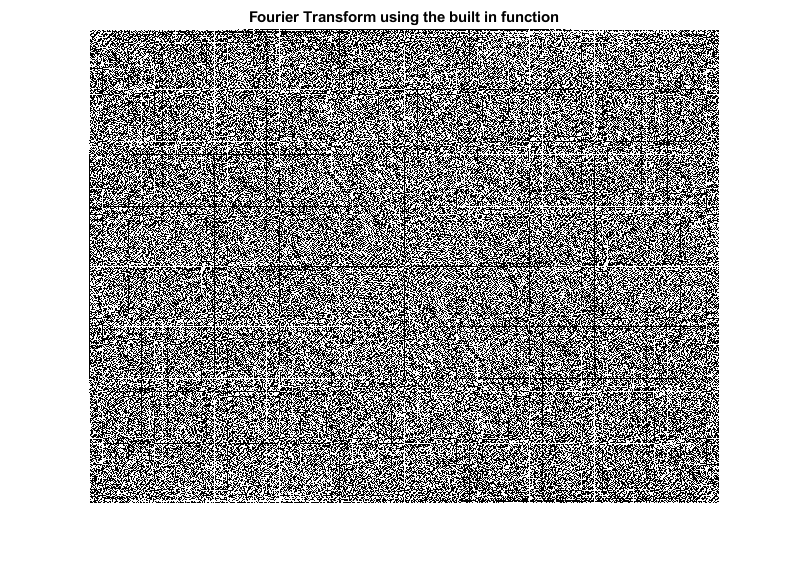

imshow(real(FFT)); title('Fourier Transform using the built in function')

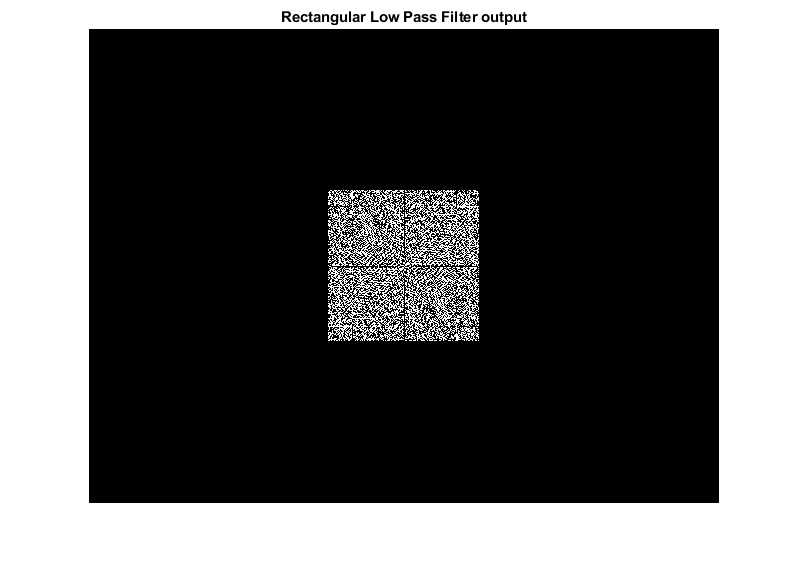



%%% Rectangular LOW PASS FILTER
D=75; % filter size parameter 
Low(1:M,1:N)=0;
Low(0.5*M-D:0.5*M+D,0.5*N-D:0.5*N+D)=1;

Filter_out_rectangular = Fft .* Low;
imshow(real(Filter_out_rectangular)); title('Rectangular Low Pass Filter output')

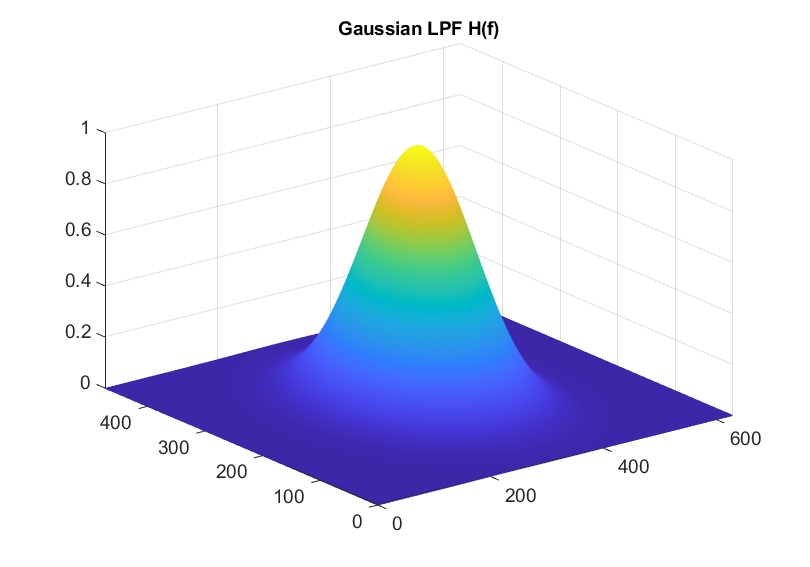




%%% Gaussian Low Pass Filter %%%
R=50; % filter size parameter 
X=0:N-1;
Y=0:M-1;
[X, Y]=meshgrid(X,Y);
Cx=0.5*N;
Cy=0.5*M;
Lo=exp(-((X-Cx).^2+(Y-Cy).^2)./(2*R).^2);

mesh(X,Y,Lo)
axis([ 0 N 0 M 0 1])
h=gca; 
get(h,'FontSize') ;
set(h,'FontSize',14);
title('Gaussian LPF H(f)','fontsize',14);

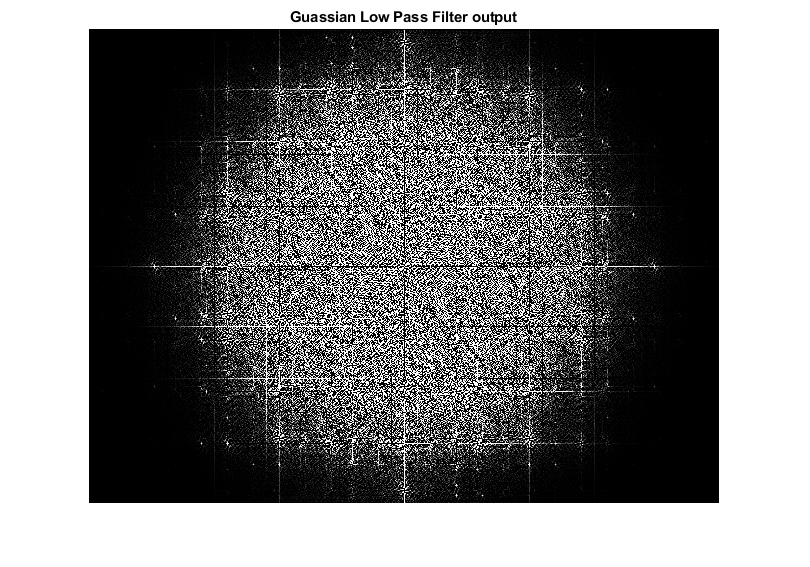


Filter_out_gaussian = Lo .* Fft;
imshow(real(Filter_out_gaussian)); title('Guassian Low Pass Filter output')

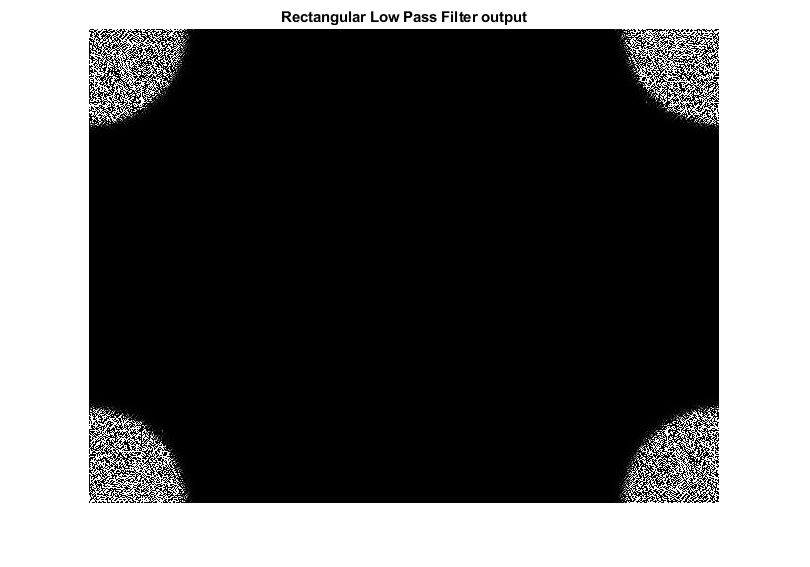



%%% Butter_worth Low Pass Filtering %%%
FT_img = fft2(double(img_input));
order = 20; %filter order
  
% Assign Cut-off Frequency
D0 = 75; % one can change this value accordingly
  
% Designing filter
u = 0:(M-1);
v = 0:(N-1);
idx = find(u > M/2);
u(idx) = u(idx) - M;
idy = find(v > N/2);
v(idy) = v(idy) - N;
[V, U] = meshgrid(v, u);
D_ = sqrt(U.^2 + V.^2);
H = 1./(1 + (D_./D0).^(2*order));
Filter_out_buterworth = H.*FT_img;
imshow(real(Filter_out_buterworth)); title('Rectangular Low Pass Filter output')

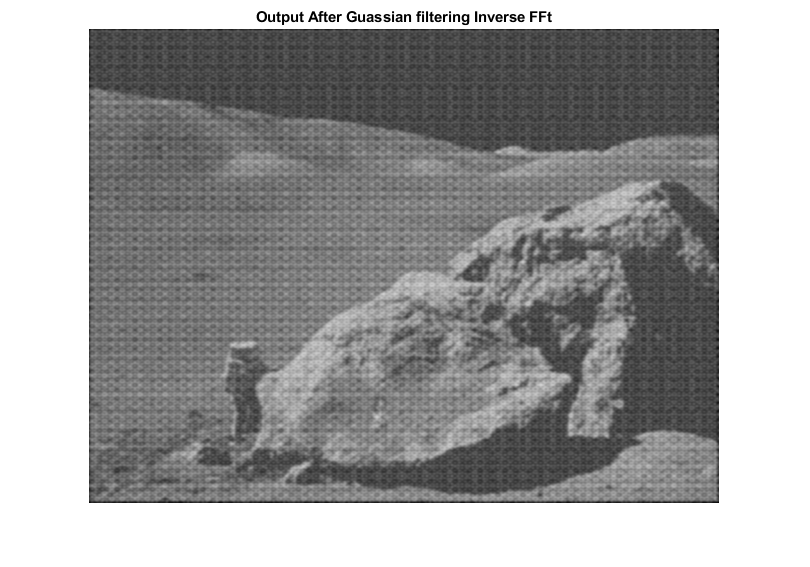



% Cumputing the Inverse Fourier Transform %

for k = 0:M-1
    
    for n = 0:M-1
    Wm(k+1, n+1) = exp(1i * 2 * pi * k * n/ M);
    end
end

for k = 0:N-1
    for n = 0:N-1
    Wn(k+1, n+1) = exp(1i * 2 * pi * k * n / N);
    end
end


%%% Guassian output %%%
f_guassian = Wm * Filter_out_gaussian * Wn/N/M;

for x = 1:M-1
    for y = 1:N-1
    f_guassian(x, y) = f_guassian(x, y) * (-1)^(x + y);
    end
end
output = im2double(abs(f_guassian));
imshow(output); title('Output After Guassian filtering Inverse FFt')

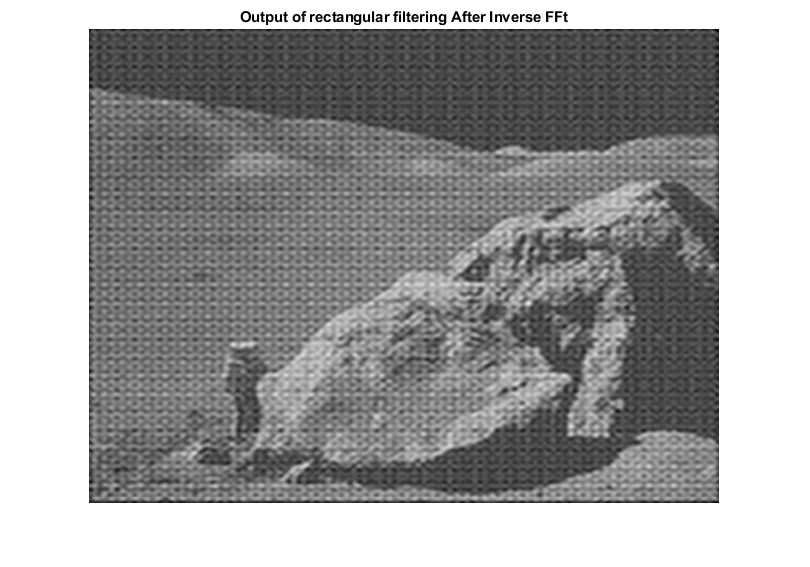


%%% Rectangular output %%%
f_rectangular = Wm * Filter_out_rectangular * Wn/N/M;

for x = 1:M-1
    for y = 1:N-1
    f_rectangular(x, y) = f_rectangular(x, y) * (-1)^(x + y);
    end
end
output = im2double(abs(f_rectangular));
imshow(output); title('Output of rectangular filtering After Inverse FFt')

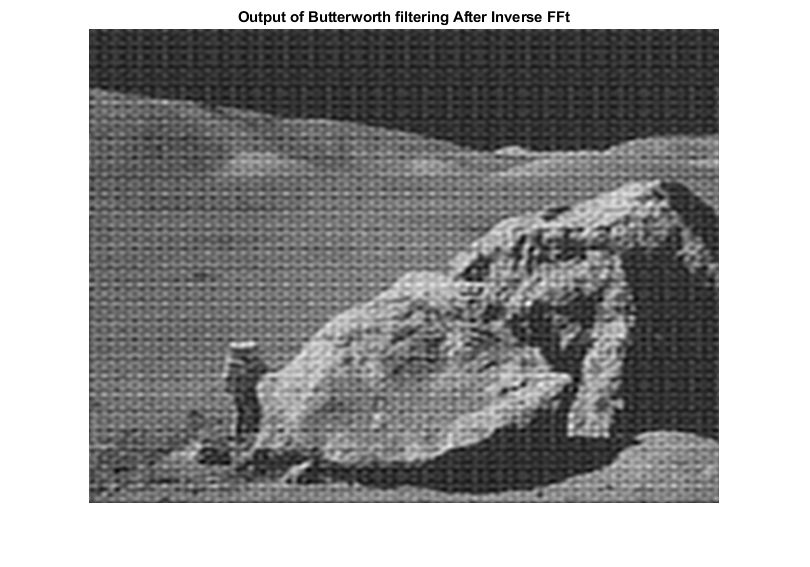



%%% Butterworth output %%%
output_image = real(ifft2(double(Filter_out_buterworth))); 
imshow(output_image, []); title('Output of Butterworth filtering After Inverse FFt')

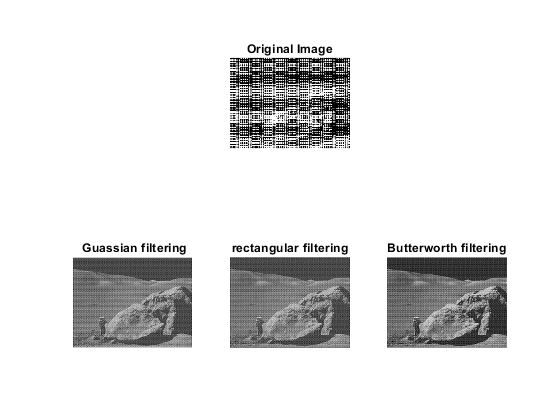


figure
subplot(2,3,2)
imshow(img_input); title("Original Image")

subplot(2,3,4)
imshow(output); title(' Guassian filtering')

subplot(2,3,5)
imshow(output); title('rectangular filtering')

subplot(2,3,6)
imshow(output_image, []); title('Butterworth filtering')